### Discussion: Fast Fourier Transform

t =          0
    0.0227
    0.0454
    0.0680
    0.0907
    0.1134
    0.1361
    0.1587
    0.1814
    0.2041


X =    -0.3024
   -0.1158
    2.1241
    0.8076
    0.5440
   -0.3696
    3.0645
    2.9933
   -1.4336
   -0.0788


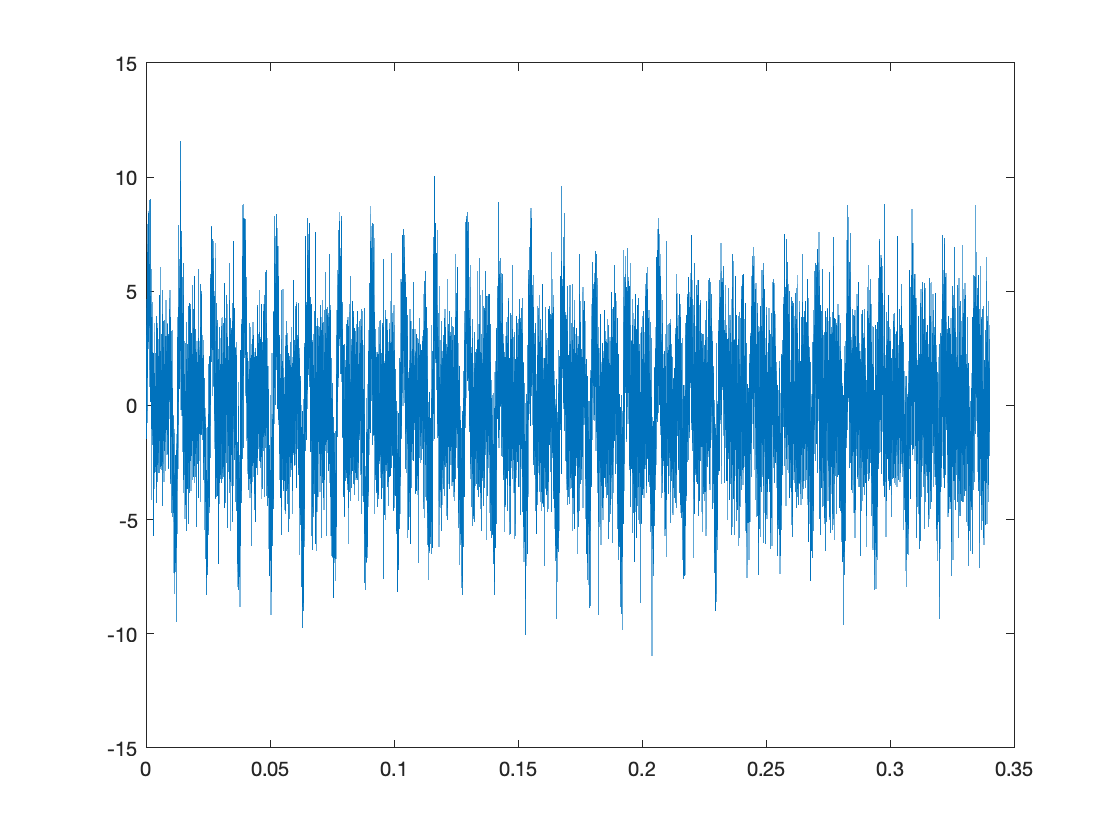

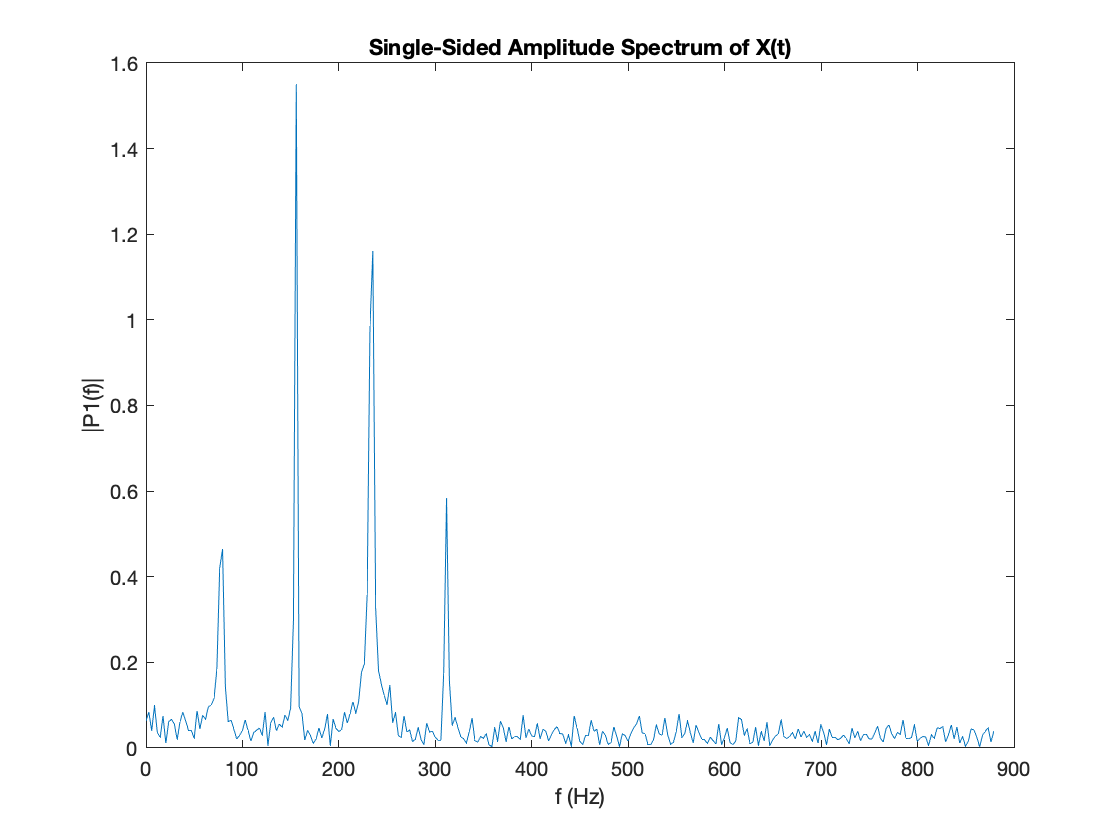

file = readtable('guitar_low_E.csv');

t = file{:,1}
X = file{:,2}
plot(t,X)

Fs = 44100; % Sampling frequency 
L = size(X,1); % Length of signal 

Y = fft(X);
P = abs(Y*2/L);
f = Fs*(0:L-1)/L;
plot(f(1:300), P(1:300)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')
